## Task 2: Generating workspace of a 2R serial link manipulator and computing the joint angles to reach the desired pose to perform pick and place

#### Generating workspace of the robot

% L1=10 & L2=7
% q1=theta1 & q2=theta2 with contrains -60 to 60 & -90 to 90 respectively 
i=1;
for q1=-60:0.1:60
    for q2=-90:0.1:90
        x(i)=(10*cosd(q1)+10*cosd(q1+q2));
        y(i)=(10*sind(q1)+10*sind(q1+q2));
        i=i+1;
    end
end
x=x';
y=y';
scatter(x,y)

#### Finding the angles

Lk(1) = Link([0 0 10 0]);
Lk(2) = Link([0 0 10 0]);
twolink = SerialLink(Lk, 'name', 'two link');
T=transl(12,-10,0)*trotz(45,'deg')

T =     0.7071   -0.7071         0   12.0000
    0.7071    0.7071         0  -10.0000
         0         0    1.0000         0
         0         0         0    1.0000


q= twolink.ikine(T,[-1 -1],[1 1 0 0 0 0])

q =    -0.0202   -1.3490


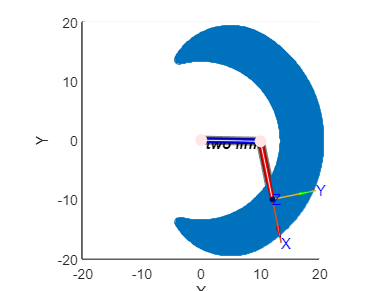

twolink.plot(q)